# Explore the dynamics of a 1-dof Spring Mass Damper

In this example we're going to derive and then implement the equations of motion for 1-dof Spring Mass Damper system. Specifically we're going to derive the equations of motion using's ***Lagrange's method***.  The system that we're going to explore is shown below.

#  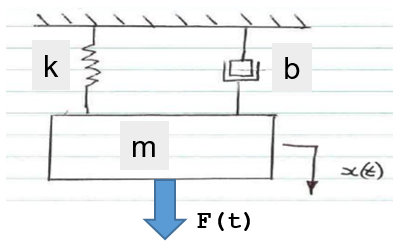

## Background:

From our year 1 class in physics and mechanics, we derived using ***Newton's 2nd law***, the equation of motion for the dynamics of a Spring Mass damper system.  Recall that it had the following form:


$$m\ldotp \ddot{x} \text{ }\text{ }+\text{ }\text{ }b\ldotp \dot{x} \text{ }\text{ }+\text{ }\text{ }k\ldotp x=F\left(t\right)$$


Today we'll use the ***Lagrangian approach*** to derive the same equations of motion for our spring mass damper.  We're going to break this problem down into the following 6 steps:

- Define Model Parameters

- Apply the governing physics

- Apply Lagrange's equation

- Isolate our expression for $\ddot{x} \text{ }\left(t\right)$

- Convert our Analytical expression for $\ddot{x} \text{ }\text{ }$into a Simulink block

- Simulate of model of this dynamic system

## Euler-Lagrange equations:

Recall our earlier class where we derived and summarised the fundamental Lagrangian equations that allow us to derive system equations of motion:

      $\frac{d}{dt}\frac{\partial L}{\partial \dot{q}_k} - \frac{\partial L}{\partial q_k} = Q_k $        where         $Q_k = 
\sum_{i=1}^{Nf_{nc}}
\pmatrix{
\vec{F_i} \thinspace . \thinspace \frac{\partial \vec{v \thinspace _i}}{\partial \dot{q \thinspace}_k}
}  \enspace + \enspace
\sum_{j=1}^{N\tau_{nc}}
\pmatrix{
\vec {\tau_j} \thinspace . \thinspace \frac{\partial \vec{\omega \thinspace _j}}{\partial \dot{q \thinspace}_k}
}
$

where:

- L       :    is the system Lagrangian, ie:  L = KE - PE

- $q_k$     :    is  the $k^{th}$ generalised co-ordinate 

- $Q_k$     :    is the generalised force associated with the $k^{th}$ generalised co-ordinate $q_k$

- $Nf_{nc}$  :    is the number of active NON conservative forces

- $N\tau_{nc}$ :    is the number of active NON conservative TORQUES

- $\vec{v_i}$      :    is the velocity vector of the point associated with the applied force.

- $\vec{\omega_i}$     :    is the angular velocity about the point associated with the applied torque. 

`Bradley Horton : 13-Sep-2016, bradley.horton@mathworks.com.au`           

# STEP_1:  Define Model parameters

 Define some Symbolic variables that parameterise our model:

syms  m  k  b  F

And here are some variables associatd with our $x\left(t\right)$, $\dot{x} \left(t\right)$ and $\ddot{x} \left(t\right)$

syms          t       x(t) 
syms              THE_X    THE_XD      THE_XDD
HOLDER_list = [   THE_X,   THE_XD,     THE_XDD];
actual_list = [       x,   diff(x,t),  diff(x,t,2)];

# STEP_2:  Apply the governing physics  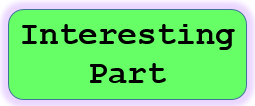

v  = diff(x,t);  % velocity
KE = 0.5*m*v^2;  % KINETIC energy
PE = 0.5*k*x^2;  % POTENTIAL energy
L  = KE - PE     % our Lagrangian

# **ATTENTION:**  you have a new friend, its name is `diff()`

When it comes to applying the [*Chain Rule of differentiation*](https://en.wikipedia.org/wiki/Chain_rule) - ***CONGRATULATIONS*** you've already earnt your merit badge in 1st year maths.  SO I know .... that YOU know .... how to do things like this:

syms z(t) y(t)
g     = (sin(z)).^2

So what's $\frac{\mathit{\text{d}}g}{\mathit{\text{dt}}}$

dg_dt = diff(g,t)    % <------ YOU can do this !

In this course we'll spend ALOT of time constructing expressions that contain DOZENS, sometimes HUNDREDS or even THOUSANDS of terms.  For example, expressions that look like this:

f = bh_some_ct_example_func(y, z, t);

So if we need to compute things like $\frac{\mathit{df}}{\mathit{dt}}$, let's allow MATLAB to do in 1 microsecond what could take you minutes/hours to do by hand, eg:

df_dt = diff(f,t);

So `diff()`  - it computes the analytical derivative of a symbolic function.  You can read more about it in MATLAB's help browser:

% doc symbolic differentiation

 We'll be using it alot, so let's start practicing with it now !

# STEP_3:  Apply Lagrange's equation - PART 1 of 3  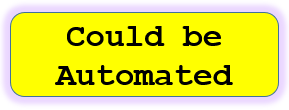

Now let's start applying Lagranges equation $\frac{d}{dt}\frac{\partial L}{\partial \dot{x}} - \frac{\partial L}{\partial x} $ :

                   % OLD_LIST       NEW_LIST
L_new   = subs(L, actual_list,   HOLDER_list);

  Our 1st piece is:  $ \frac{\partial L}{\partial x} $        

dLdx    = diff(L_new, THE_X);

 Our 2nd piece is: $\frac{\partial L}{\partial \dot{x}} $

dLdxdot =  diff(L_new, THE_XD);

 Our 3rd piece is: $\frac{d}{dt}\frac{\partial L}{\partial \dot{x}}$

                                % OLD_LIST      NEW_LIST
dLdxdot       =  subs(dLdxdot, HOLDER_list,  actual_list );
dt_of_dLdxdot = diff(dLdxdot, t);

Now put it all together:   $\frac{d}{dt}\frac{\partial L}{\partial \dot{x}} - \frac{\partial L}{\partial x} $

our_EOM_LHS = dt_of_dLdxdot - dLdx;
our_EOM_LHS =  subs(our_EOM_LHS, HOLDER_list, actual_list )

# STEP_3:  Apply Lagrange's equation - PART 2 of 3 

Now calculate the generalised force *Q* :


$$Q_k = 
\sum_{i=1}^{Nf_{nc}}
\pmatrix{
\vec{F_i} \thinspace . \thinspace \frac{\partial \vec{v \thinspace _i}}{\partial \dot{q \thinspace}_k}
}  \enspace + \enspace
\sum_{j=1}^{N\tau_{nc}}
\pmatrix{
\vec {\tau_j} \thinspace . \thinspace \frac{\partial \vec{\omega \thinspace _j}}{\partial \dot{q \thinspace}_k}
}
$$


Define Forces and velocities:

Fv_mat = [  F,  (-b*THE_XD),   THE_XD,   THE_XD; 
            0,            0,        0,        0;
            0,            0,        0,        0;
        ];    
F_mat = Fv_mat(:,1:2);
v_mat = Fv_mat(:,3:4);

Calculate the GENERALISED forces $Q_k$:

Q     = 0;
for zz=1:2
    F_vec = F_mat(:,zz);
    v_vec = v_mat(:,zz);
    
    dvdq  = diff(v_vec, THE_XD);    
    Q     = Q + sum( F_vec .* dvdq);
end

our_EOM_RHS = Q

# STEP_3c:  Apply Lagrange's equation - PART 3 of 3

Now put it all together:   $\frac{d}{dt}\frac{\partial L}{\partial \dot{x}} - \frac{\partial L}{\partial x} = Q$

our_EOM     = (our_EOM_LHS == our_EOM_RHS);
our_EOM     =  subs(our_EOM, HOLDER_list, actual_list )

# STEP_4:  Isolate the term of interest  $\ddot{\mathbf{x}}$

In addition to solving for $\ddot{x}$, we'll show the resulting expression using the "alternate" symbol list:

                                        % OLD_LIST      NEW_LIST
our_EOM                =  subs(our_EOM, actual_list,  HOLDER_list);

Come on ... what's  $\ddot{x}$  ?

the_expression_for_XDD = solve(our_EOM, THE_XDD)

Great, as expected we have the well known expression:

- 
$$\ddot{x} =\frac{F-k\ldotp x-b\ldotp \dot{x} }{m}$$


# STEP_5:  Convert symbolic expression into a block diagram model

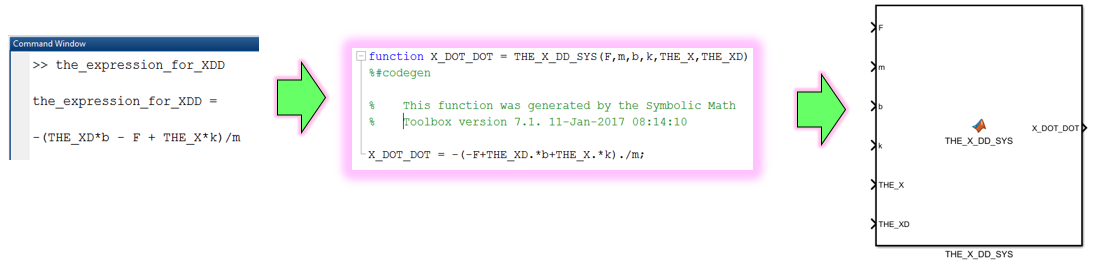

MODEL_NAME        = 'SIM_SMD_WILL_BE_DELETED';
close_system(MODEL_NAME,0); new_system(MODEL_NAME);  open_system(MODEL_NAME)

Automatically convert our $\ddot{x}$ expression into s Simulink block:

matlabFunctionBlock( [MODEL_NAME,'/THE_X_DD_SYS'], the_expression_for_XDD, ...
                         'Vars',     {F, m,b,k,THE_X,THE_XD}, ...
                         'Outputs',  {'X_DOT_DOT'}   ); 

Make the block yellow:

set_param([MODEL_NAME,'/THE_X_DD_SYS'],'BackgroundColor', '[0.996078, 1.000000, 0.705882]');                    

# STEP_6:  Simulate the model of the dynamic system

Let's use the model that we just derived, and implement it in Simulink - where we'll numerically solve it.  Recall our fundamental equation of motion for the spring mass damper system:      $m\ldotp \ddot{x} \text{ }\text{ }+\text{ }\text{ }b\ldotp \dot{x} \text{ }\text{ }+\text{ }\text{ }k\ldotp x=F\left(t\right)$ .  The parameters that we'll use for this Numerical simulation are:

- 
$$m,c,k\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }=1,4,100\text{         }$$
  

- 
$$x\left(0\right)\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }=5$$


- 
$$\dot{x} \left(0\right)\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }=0$$
 

- 
$$F\left(t\right)\text{          }=\text{ }200\ldotp u\left(t-5\right)$$


Have a look at our Simulink model .... and NOTE how we use the integrator blocks to integrate:   $\ddot{x} \to \text{ }\frac{1}{s}\text{ }\to \dot{x} \to \text{ }\frac{1}{s}\to x$

open_system('bh_a_spring_mass_model')  

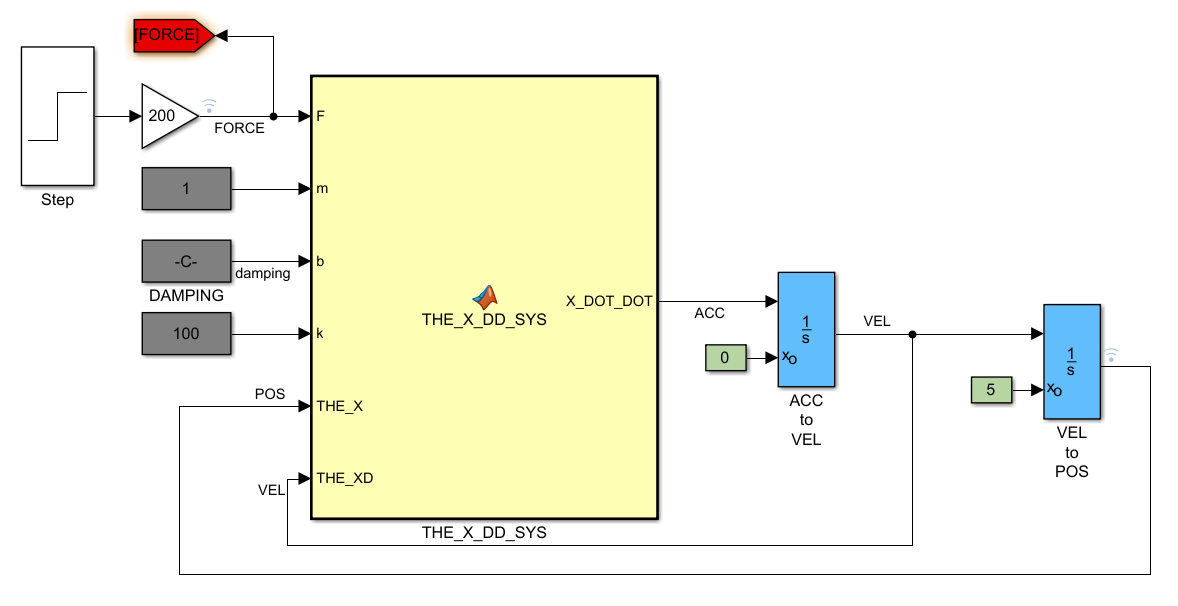

# How does this help me make a Robot write ***hello*** ?

So *IFFFF* we ***understand the system physics*** we can scale this Computational thinking approach to bigger and more interesting systems .... like 4-LINK robotic manipulators.  Capabilities that allow us to scale, include:

- `diff()`

- `matlabFunctionBlock()`

- `Simulink`

In next week's class we're going to derive the equations of motion of the 4-LINK non-planar robotic manipulator .... and we'll take a major step forward in seeing how to make it write ***hello***. Even though this is a much more complicated system, the good news for YOU is that we'll be applying the same 6 step process that you saw today, ie:

- Define Model Parameters

- Apply the governing physics

- Apply Lagrange's equation

- Isolate our expression of interest

- Convert our Analytical expression of interest into a Simulink block

- Simulate of model of this dynamic system